# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


load("wq_data.mat");
load("R_CData.mat");

### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt

% Nodes name and chlorine concentrations
Junction_All_Name = {'BW9','BW7','BW1','BW2','BW3','BW4','BW5','BW6','BW12'};
Junction_SelectIdx = net.getNodeIndex(wq_data.node_ids([1,4,7,9]));
Junction_Name = Junction_All_Name([1,4,7,9]);
Junction_HydrantIdx = net.getNodeIndex(wq_data.node_ids([2,5,8]));
Junction_Hydrant_Name = Junction_All_Name([2,5,8]);
Junction_Reservoir_Name = Junction_All_Name([6,3]);
cext = wq_data.chlorine([6,3],:);
c_nodes_HydrantObs = wq_data.chlorine([2,5,8],:);
c_nodes_Obs = wq_data.chlorine([1,4,7,9],:);


### Graph Creation Preparation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);


### Graph Plotting

Setup general chemical simulation parameters.

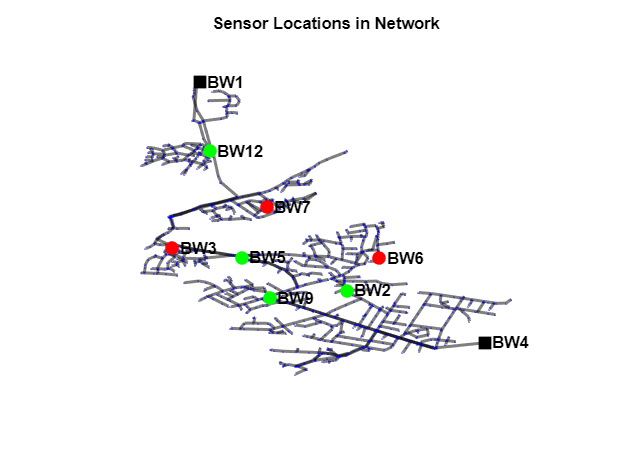

% Plot the sensor location on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 2;
p1.EdgeColor = 'k';
p1.MarkerSize = 0.01;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,Junction_SelectIdx,'NodeColor','green','MarkerSize',8);
labelnode(p1,Junction_SelectIdx,Junction_Name);
highlight(p1,Junction_HydrantIdx,'NodeColor','red','MarkerSize',8);
labelnode(p1,Junction_HydrantIdx,Junction_Hydrant_Name);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,Junction_Reservoir_Name);
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
% p1.EdgeCData = R_CData;
% hcb_R = colorbar;
% colormap('jet');
% hcb_R.Label.String = 'Pipe Roughness Group';
% hcb_R.Label.FontSize = 12;
axis('off')
title('Sensor Locations in Network')

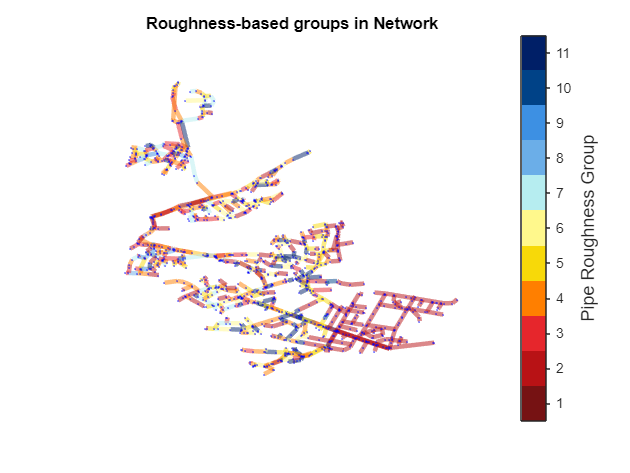

% Plot the Roughness group on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 3;
p1.EdgeColor = 'k';
p1.MarkerSize = 1e-10;

p1.NodeColor = 'b';
p1.NodeLabel = '';
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
p1.EdgeCData = R_CData;
cmap=[118 18 19; 
     184 18 21; 
     230 38 44; 
     255 127 0; 
     247 217 9; 
     255 248 140; 
     182 237 240; 
     107 174 232; 
     61 144 227; 
     0 66 135; 
     0 31 103];
cmap=cmap/255; 
colormap(cmap);
hcb = colorbar;
hcb.TicksMode = 'manual';
set(hcb,'Tickdir','out');
caxis([0,11]);
set(hcb,'YTick',0.5:1:10.5);
set(hcb,'TickLabels',{'1','2','3','4','5','6','7','8','9','10','11'});
hcb.Label.String = 'Pipe Roughness Group';
hcb.Label.FontSize = 12;
axis('off')
title('Roughness-based groups in Network')

### Chlorine Simulation

Setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% % Link bulk reaction coefficients
% lambda = 0.5*ones(np,1); % units of days^-1
% net.setLinkBulkReactionCoeff(1:np, -lambda);
% net.setOptionsPipeBulkReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);
base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;


% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:1+4*nt,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:1+4*nt,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

% Get the simulated and observed data
c_nodes_Sim = c_nodes(Junction_SelectIdx,:);
c_nodes_Sim = c_nodes_Sim(:,1:end-1);
c_nodes_HydrantSim = c_nodes(Junction_HydrantIdx,:);
c_nodes_HydrantSim = c_nodes_HydrantSim(:,1:end-1);
c_nodes_Reservoir = pattern_cext;

% split the data
Sim_train = c_nodes_Sim(:,2*96+1:3*96);
Sim_val = c_nodes_Sim(:,3*96+1:end);
Sim_Hydrant_train = c_nodes_HydrantSim(:,2*96+1:3*96);
Sim_Hydrant_val = c_nodes_HydrantSim(:,3*96+1:end);

Obs_train = c_nodes_Obs(:,2*96+1:3*96);
Obs_val = c_nodes_Obs(:,3*96+1:end);
Obs_Hydrant_train = c_nodes_HydrantObs(:,2*96+1:3*96);
Obs_Hydrant_val = c_nodes_HydrantObs(:,3*96+1:end);

% Combine the two data sets
Junction_CombinedIdx = [Junction_SelectIdx,Junction_HydrantIdx];
Obs_Combined_train = [Obs_train; Obs_Hydrant_train];
Obs_Combined_val = [Obs_val; Obs_Hydrant_val];
Sim_Combined_train = [Sim_train; Sim_Hydrant_train];
Sim_Combined_val = [Sim_val; Sim_Hydrant_val];

% Calculate the original mse
mse_function = @(sim,obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
mse_before = mse_function(Sim_Combined_val, Obs_Combined_val);


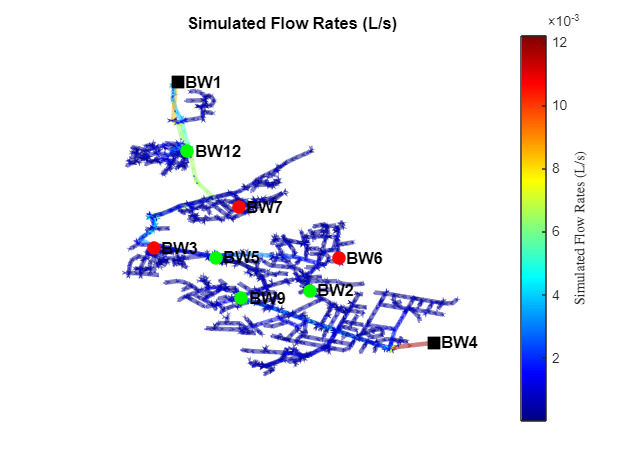

% Plot the flow direction
edgeweights = abs(q(:,1)); % t=1, steady state
A_Dir = [A12,A10];
AdjA_Dir = sparse(size(A_Dir,2),size(A_Dir,2));
for i = 1:size(A_Dir,1)
    u = find(A_Dir(i,:) == -1);
    v = find(A_Dir(i,:) == 1);
    edgemap(i,:) = [u v i];
    if isnan(edgeweights)
        AdjA_Dir(u,v) = 1;
    else
        AdjA_Dir(u,v) = edgeweights(i);
    end
end  

edgemap = sortrows(edgemap);
G1 = digraph(AdjA_Dir);

figure,
p1 = plot(G1,'XData',XY(:,1),'YData',XY(:,2));
p1.ShowArrows = 'on';
p1.MarkerSize = 0.05;
p1.LineWidth = 3;
p1.NodeLabel = '';
axis('off')
p1.EdgeColor = 'k';
p1.NodeColor = 'b';
highlight(p1,Junction_SelectIdx,'NodeColor','green','MarkerSize',8);
labelnode(p1,Junction_SelectIdx,Junction_Name);
highlight(p1,Junction_HydrantIdx,'NodeColor','red','MarkerSize',8);
labelnode(p1,Junction_HydrantIdx,Junction_Hydrant_Name);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,Junction_Reservoir_Name);
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
p1.EdgeCData = G1.Edges.Weight;

hcb = colorbar;
hcb.Label.String = 'Simulated Flow Rates (L/s)';
hcb.Label.Interpreter = 'latex';

colormap("jet")

axis('off')
title('Simulated Flow Rates (L/s)')

### Trial-and-Error calibration (No group)

The trial and error calibration is a step by step process, we divide the network into pipe groups and manually adjust the decay coefficient of pipes upstream of the sensors to minimize the deviation between simulated and observed data.

% Consider the whole network together and assign the same decay parameter
% Set one single bulk reaction coefficient as the whole decay rate
% coefficient, here we start from 0.5
lambda = 0.5*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1); 
quality_res_1 = net.getComputedQualityTimeSeries;

c_nodes_1 = quality_res_1.NodeQuality';
c_nodes_Sim_1 = c_nodes_1(Junction_SelectIdx,1:end-1);
c_nodes_Sim_Hydrant_1 = c_nodes_1(Junction_HydrantIdx,1:end-1);
c_nodes_Sim_Combined_1 = [c_nodes_Sim_1;c_nodes_Sim_Hydrant_1];
Sim_Combined_1_val = c_nodes_Sim_Combined_1(:,3*96+1:end);
mse_after_1 = mse_function(Sim_Combined_1_val,Obs_Combined_val);

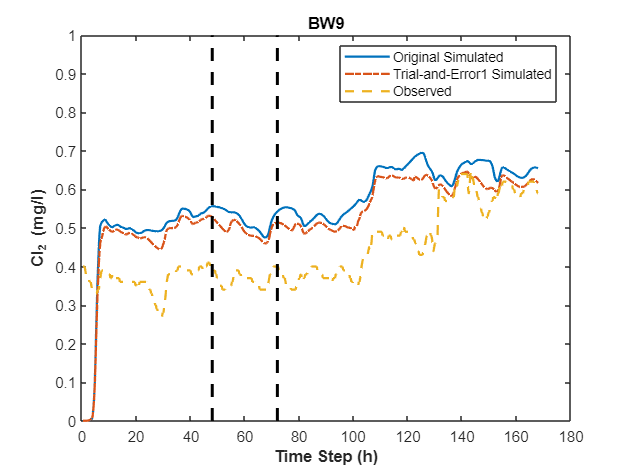

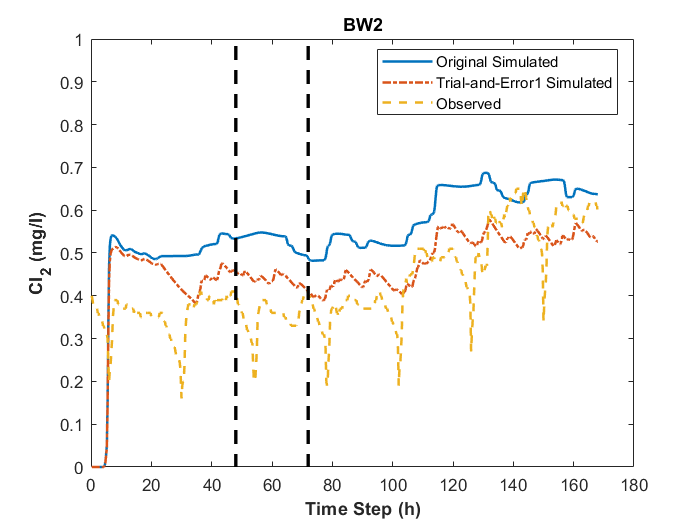

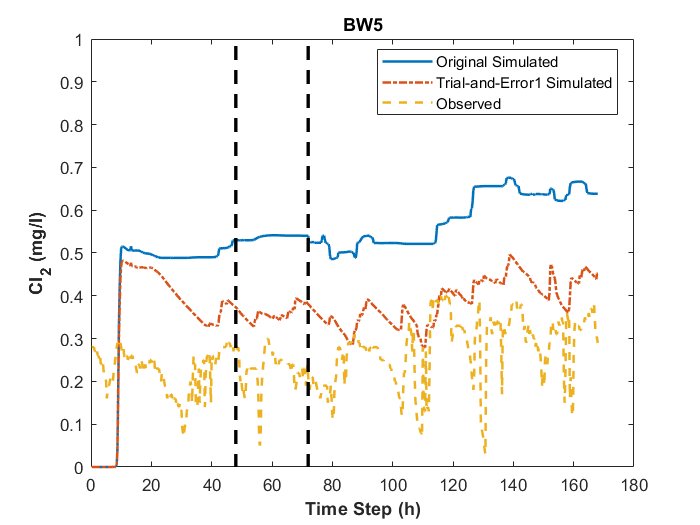

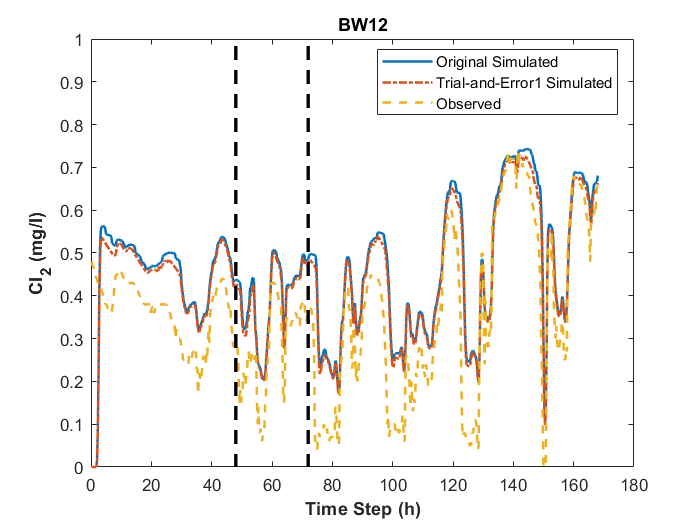

% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_1(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','Trial-and-Error1 Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end

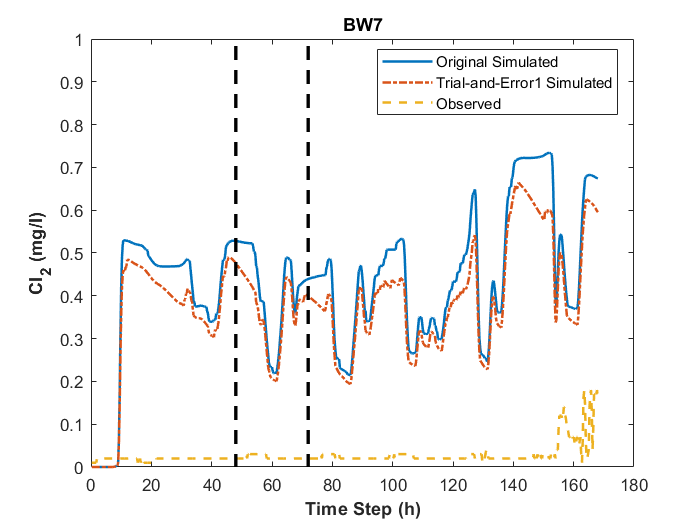

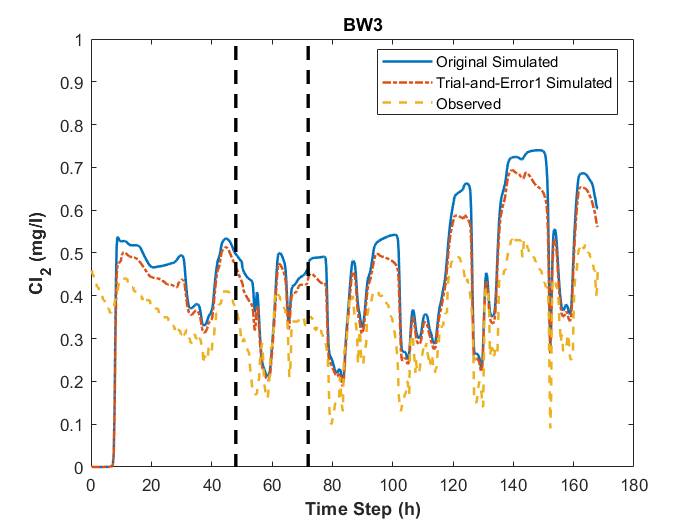

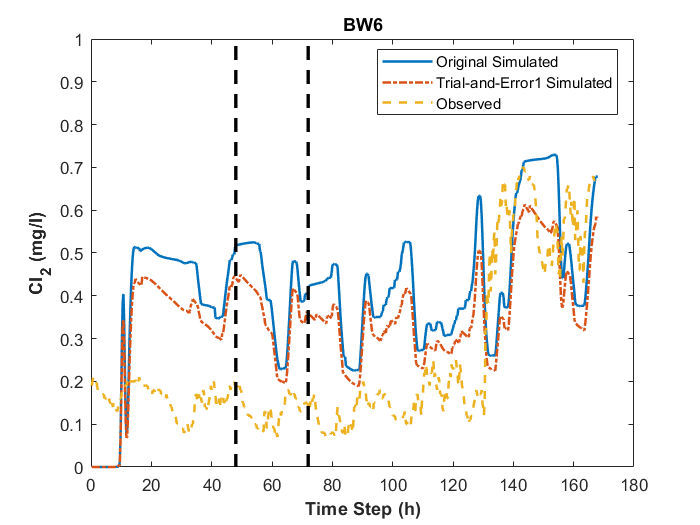


% figures for simulated and observed data (Hydrants)
for i = 1:size(c_nodes_HydrantObs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_HydrantSim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_Hydrant_1(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_HydrantObs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','Trial-and-Error1 Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Hydrant_Name{i})
end